%7
alpha=zeros(1,201)

alpha =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


tan(pi/2)

ans = 1.6331e+16

theta=3.71/180*pi

theta = 0.0648

v=zeros(1,201)

v =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


beta=zeros(1,201)

beta =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


dt=0.001

dt = 1.0000e-03

J=0.05052

J = 0.0505

r=0.2

r = 0.2000

for k=1:100
    beta(k)=(90*r*sin(theta-atan(tan(alpha(k))/sqrt(1+alpha(k)*alpha(k))))-0*r*sin(theta+atan(tan(alpha(k))/sqrt(1+alpha(k)*alpha(k)))))/J;
    v(k+1)=v(k)+beta(k)*dt;
    alpha(k+1)=alpha(k)+v(k)*dt+beta(k)*dt*dt/2;
end
k=101

k = 101

beta(k)=(90*r*sin(theta-atan(tan(alpha(k))/sqrt(1+alpha(k)*alpha(k))))-0*r*sin(theta+atan(tan(alpha(k))/sqrt(1+alpha(k)*alpha(k)))))/J;
for k=101:200
    beta(k)=(90*r*sin(theta-atan(tan(alpha(k))/sqrt(1+alpha(k)*alpha(k))))-80*r*sin(theta+atan(tan(alpha(k))/sqrt(1+alpha(k)*alpha(k)))))/J;
    v(k+1)=v(k)+beta(k)*dt;
    alpha(k+1)=alpha(k)+v(k)*dt+beta(k)*dt*dt/2;
end
k=201

k = 201

alpha(end)

ans = -0.0425

beta(k)=(90*r*sin(theta-atan(tan(alpha(k))/sqrt(1+alpha(k)*alpha(k))))-61.2293*r*sin(theta+atan(tan(alpha(k))/sqrt(1+alpha(k)*alpha(k)))))/J;
-0.1:0.001:0.1

ans =    -0.1000   -0.0990   -0.0980   -0.0970   -0.0960   -0.0950   -0.0940   -0.0930   -0.0920   -0.0910   -0.0900   -0.0890   -0.0880   -0.0870   -0.0860   -0.0850   -0.0840   -0.0830   -0.0820   -0.0810   -0.0800   -0.0790   -0.0780   -0.0770   -0.0760   -0.0750   -0.0740   -0.0730   -0.0720   -0.0710   -0.0700   -0.0690   -0.0680   -0.0670   -0.0660   -0.0650   -0.0640   -0.0630   -0.0620   -0.0610   -0.0600   -0.0590   -0.0580   -0.0570   -0.0560   -0.0550   -0.0540   -0.0530   -0.0520   -0.0510


alpha

alpha =          0    0.0000    0.0000    0.0001    0.0002    0.0003    0.0004    0.0006    0.0007    0.0009    0.0011    0.0014    0.0017    0.0019    0.0022    0.0026    0.0029    0.0033    0.0037    0.0041    0.0046    0.0050    0.0055    0.0060    0.0065    0.0071    0.0076    0.0082    0.0088    0.0095    0.0101    0.0108    0.0115    0.0122    0.0129    0.0136    0.0144    0.0152    0.0160    0.0168    0.0176    0.0185    0.0193    0.0202    0.0211    0.0220    0.0230    0.0239    0.0249    0.0258


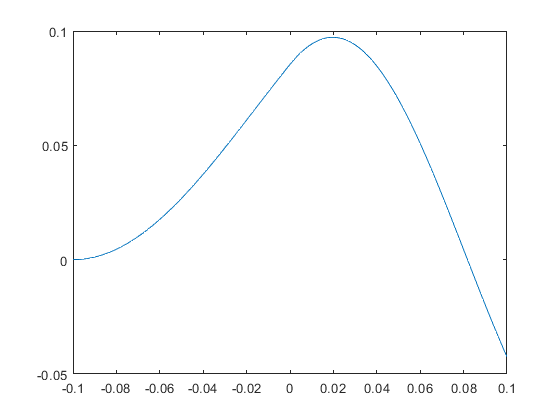

plot(-0.1:0.001:0.1,alpha)

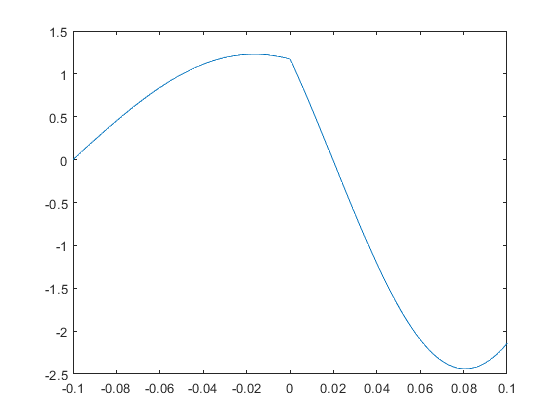

plot(-0.1:0.001:0.1,v)

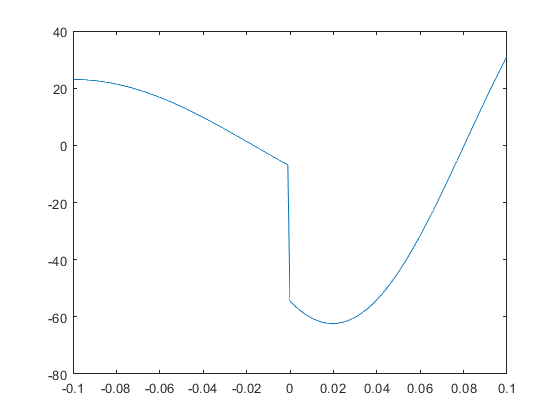

plot(-0.1:0.001:0.1,beta)